# Linear Control Design II - Group Work Problem Module 11 

## Description

This group work module deals with the design of a full state feedback controller for the model of the aircraft analysed in Group Work Module 5 (the SISO model).

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729; -0.475; 0.153; 0]

B =       0.00729
       -0.475
        0.153
            0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

**Problem 1**

Transform the continuous time model given in Module 5 into the controller canonical form.

% Your solution goes here:
chP = poly(A)

chP =             1       0.6358      0.93887      0.51163    0.0036741


%Define P matrix

p1 = B;
p2 = A*p1 + chP(2)*p1;
p3 = A*p2 + chP(3)*p1;
p4 = A*p3 + chP(4)*p1;
P = [p4 p3 p2 p1]

P =    -0.0076724      0.21689      0.48998      0.00729
    -0.056326     -0.11871     -0.24789       -0.475
    0.0045343      -1.3631      -0.1804        0.153
      -1.3726     -0.20036      0.11476            0



A_cc = inv(P)*A*P

A_cc =   -6.1062e-16            1   3.6863e-18  -2.7756e-17
   6.4185e-16    9.541e-18            1    6.245e-17
  -2.2204e-16  -2.4286e-17  -6.4185e-17            1
   -0.0036741     -0.51163     -0.93887      -0.6358


B_cc = inv(P)*B

B_cc =   -4.1315e-18
   1.8459e-17
   -5.166e-18
            1


C_cc = C*P

C_cc =     -0.056326     -0.11871     -0.24789       -0.475


D_cc = D

D_cc =      0


**Problem 2**

It is desired to assign the eigenvalues through state feedback such that the damping ratio for the least damped eigenvalues is increased to approximately 0.7, and such that natural frequencies and time constants are approximately unchanged. A reasonable assignment could be:


$$\lambda = \left\{\matrix{-0.01 \cr -0.6 \cr -0.5\pm0.5j} \right.$$


Find the gain matrix K for the controller


$$u = -\textbf{Kx}+r$$


by applying the method from Section 4.3.1 in the textbook. Check that the eigenvalues of the closed-loop system have been assigned as desired.

% Your solution goes here:
syms lambda
eigs = [-0.01 -0.6 -.5+.5j -.5-.5j];
charPoly = expand(prod(lambda - eigs))

$$charPoly = \lambda^{4}+\frac{161\,\lambda^{3}}{100}+\frac{279\,\lambda^{2}}{250}+\frac{311\,\lambda }{1000}+\frac{3}{1000}$$

a = chP;
alpha = sym2poly(charPoly);
K_cc = flip((alpha(2:end)-a(2:end)))

K_cc =   -0.00067415     -0.20063      0.17713       0.9742


K_l = K_cc*inv(P)

K_l =       -0.5869      -1.9909      0.21453     0.086175


eig(A-B*K_l)

ans =         -0.01 +          0i
         -0.5 +        0.5i
         -0.5 -        0.5i
         -0.6 +          0i


**Problem 3**

Add the controller to the Simulink open-loop model and carry out a simulation with the function shown on Figure 1 as input to the closed-loop system. Plot the states, the output and the rudder angle.

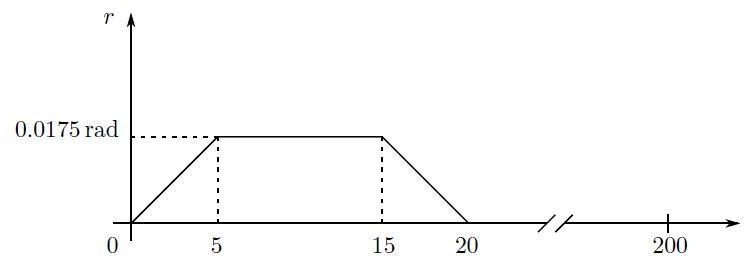


$$Figure\,1: Input\,signal\,to\,the\,closed\,loop\,system.$$


% Your solution goes here:



**Problem 4**

Repeat Problems 2 and 3 with the largest time constant decreased by a factor 50 and by applying Ackermann's formula (the Matlab's function is called *acker()*). The Ackermann's formula has to be applied to the original model.

% Your solution goes here:



**Problem 5**

Repeat Problem 4 for a discrete time controller. Do not forget to convert the eigenvalues to the discrete domain. The discrete time controller must be tested together with the continuous time plant. To enable interaction between the continuous and discrete time parts of the control loop do not forget to insert digital-to-analogue (DAC) and analogue-to-digital (ADC) converters into the system. The DAC is usually a zero-order hold, and such a block is available in Simulink's discrete library. The ADC is implemented in Simulink as a discrete transfer function (same library) with 1 as numerator and denominator, as shown in Figure 2. All discrete blocks use the parameter *Sample Time*, which has to be chosen in a suitable manner.

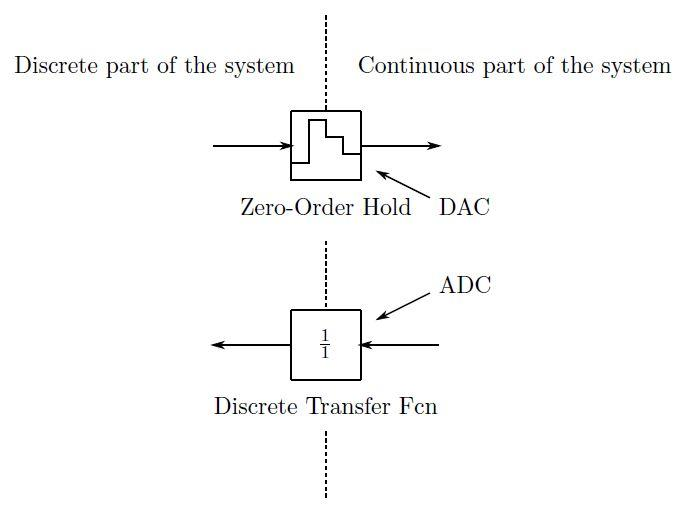


$$Figure\,2:Simulink\,discretization\,blocks.$$


% Your solution goes here:



**Problem 6**

Compare the system responses from Problem 4 and 5, and discuss the effect of discretization on the system performance.

% Your solution goes here:

